# Feed jitter: coupled feed, strut and dish model

This live script estimates how much the feed (the receiver hardware held above the dish) shakes in gusty wind, and how that shaking turns into beam pointing error. It sweeps the strut stiffness and the elevation angle and reports two numbers for every case: a statistical RMS and an expected peak (MAX).

**Why it matters.** At 225 GHz the wavelength is about 1.3 mm and the beam is only about 0.8 mrad wide. Losing a tenth of that beamwidth to pointing error already costs signal, so jitter of a few micro-radians matters.

### How to use

Run the whole script with **Run**, or run it section by section from the top. Every section uses variables created in the sections above it. Change inputs only in the Parameters section.

### Prerequisites

Basic statics and vibration (a mass on a spring has natural frequency $\omega_n=\sqrt{k/m}$), matrix algebra, and the idea of a power spectrum. Everything else is introduced where it is used. Numbered references such as [1] point to the References section near the end.

### Functions used in this script

These functions live at the bottom of the script - here's a description of each one.

- `buildModel(P, k)` assembles the whole structure for a given strut stiffness $k$, using parameter *m* as the rigid body feed-truss mass. It incorporates the strut joint springs,and the spring element of the truss, and it computes the modes + modal damping matrix. It then builds the load matrix $B$ and output matrix $F$. It returns `M`, `K`, `C`, `B`, `Fy`, the natural frequencies `fn`, and the dominant feed lateral frequency `f_feed_lat`.

- `addLink(K, ia, Ta, ib, Tb, Kb)` adds a 6×6 spring $K_b$ between 2 points to link 2 bodies or 1 body to the ground (fixed referencE).

- `rigidMap(r)` returns the 6×6 matrix that gives the motion of a point (at offset) [$\mathbf{r}$] on a rigid body: $\mathbf{x}_p=\mathbf{x}+\vec{\theta}\times\mathbf{r}$.

- `skew(r)` builds the cross-product matrix $[\mathbf{r}]_\times$, so that $[\mathbf{r}]_\times\mathbf{v}=\mathbf{r}\times\mathbf{v}$.

- `localAxes(u)` returns the rotation from the dish axes to a strut's own axes, with local $x$ along the strut.

- `windExcite(P, el)` turns an elevation angle into the five wind load coefficients, for both the fluctuating gust load and the mean-wind load.

## Model at a glance

The structure is a set of masses connected by springs:

- **m1 (feed):** a rigid body that has all 6 degrees of freedom (DOF). Its centre of mass basically sits at height $z_{feed}$ above the dish vertex.

- **Struts:** $n$ identical tubes running from the dish rim to a small ring on m1. Each strut is basically composed of beam elements that have mass and can stretch, bend and twist. A joint spring at each end stands in for the bolted connection.

- **m2 (dish and hub):** another 6-DOF rigid body, with its reference point at the dish vertex. Its CoM is offset from the vertex!

- **Base:** a translational spring $k_{base}$ and a rotational spring $k_{\theta}$ tie m2 to the ground (as in GND, or fixed reference). *The rotational spring element is required - without it the dish could spin freely and the jitter would grow without limit!*

- **Damping:** every vibration mode loses energy at $\zeta=2\%$ of critical damping. (Arbitrary number)

- **Wind:** a turbulent gust $u'(t)$ pushes on both the feed and the dish.

**Coordinates.** Everything is written in the*** dish frame.*** The origin is the dish vertex, $+z$ is the boresight (the direction the dish looks), $x$ is the elevation axis, and $+y$ completes the right-handed set. All motions are small, so the model is linear.

### Equations of motion

$\mathbf{q}$ represents the state displacement and rotation information-bearing vector. Newton's second law for the whole structure becomes a single matrix equation:


$$M\ddot{\mathbf{q}}+C\dot{\mathbf{q}}+K\mathbf{q}=B\mathbf{u},\qquad \mathbf{y}=F\mathbf{q}$$


$M$ holds the masses and inertias, $K$ the spring stiffnesses and $C$ the damping. $B$ says where the loads $\mathbf{u}$ act, and $F$ picks out the outputs $\mathbf{y}$ we care about. The Control System Toolbox object `mechss` stores a model in exactly this second-order form [15].

clc; clear; close all;

## Parameters

All inputs are in SI units and live in one structure `P`, so a single variable carries the whole design into the functions at the bottom of the script.

- **Geometry:** The feed, dish shell and hub are described by their dimensions. Their masses and inertias are computed from those dimensions in the next section.

- **Design Values: **The dish radius, focal length, shell thickness, operating frequency, etc.

- **Placeholders:** The dish density, hub size, joint stiffnesses and wind coefficients (`rho_dish`, `h_hub`, `k_joint_ax`, `C_N`, `C_S`, `C_M`) are placeholders. Replace them with drawings, test data or wind-tunnel data before trusting absolute numbers.

- **Sweep Values:** The sweep varies the strut axial stiffness $k=EA/L$. It does this by changing Young's modulus $E$ of the tube, so the bending stiffness scales with it.

**Beam deviation factor (BDF).** When a prime-focus feed moves sideways by $\delta$, the beam tilts by about $\mathrm{BDF}\,\delta/f$, in the opposite direction. A curved reflector steers the beam less than a flat mirror would, so $\mathrm{BDF}<1$. Lo's approximation [1] is


$$\mathrm{BDF}\approx\frac{1+k_{B}\,(D/4f)^2}{1+(D/4f)^2}$$


with $k_{B}\approx0.36$. Ruze [2] derived the same behaviour from the aperture phase error and showed $k_{B}$ depends weakly on the illumination taper (roughly 0.3 to 0.4). Baars [3] tabulates it for radio telescopes. The formula holds for small offsets, up to a few beamwidths, which covers micro-metre jitter. 

**Beamwidth.** The half-power beamwidth (HPBW) is about $1.2\lambda/D$ for a typical tapered illumination [3]. A common pointing budget is **one tenth of it. A **pointing error of HPBW/10 costs about 3% of the on-axis gain.

% Feed / subreflector lump (m1): solid cylinder of radius r_feed and length h_feed
P.m1      = 6.5;                       % [kg]
P.r_feed  = 0.10;                      % [m] feed body radius
P.h_feed  = 0.20;                      % [m] feed body length along the boresight
P.z_feed  = 1.01;                      % [m] feed centre of mass height above the vertex
P.r_ring  = 0.10;                      % [m] radius of the strut attachment ring on m1

% Dish shell (part of m2): thin paraboloid z = r^2/(4 f_dish), 0 <= r <= r_dish
P.r_dish     = 1.0;                    % [m] rim radius
P.f_dish     = 0.91;                   % [m] focal length
P.thick_dish = 0.0127;                 % [m] shell thickness (0.5 in)
P.rho_dish   = 1050;                   % [kg/m^3] effective density (placeholder, ~45 kg shell)
P.z_rim      = P.r_dish^2/(4*P.f_dish); % [m] rim height above the vertex

% Hub (part of m2): solid cylinder behind the vertex that tilts with the dish
P.m_hub  = 45;                         % [kg] mount + hub (tower_tip_mass in macrostructure)
P.r_hub  = 0.10;                       % [m] hub radius (dish_hub_radius in macrostructure)
P.h_hub  = 0.20;                       % [m] hub depth (placeholder)
P.z_hub  = -P.h_hub/2;                 % [m] hub centre of mass height (negative = behind)

% Struts
P.n_truss = 3;                         % number of struts
P.N_el    = 4;                         % beam elements per strut
P.m_truss = 1.5;                       % [kg] mass of one strut
P.d_o     = 0.05;                      % [m] tube outer diameter (sets I/A ratio)
P.t_wall  = 2e-3;                      % [m] tube wall
P.nu      = 0.33;                      % [-] Poisson ratio (torsion G = E/2(1+nu))
P.E_ref   = 69e9;                      % [Pa] aluminium, only for the reference k

% Joints (two per strut, identical). Rotational value near-pinned.
P.k_joint_ax  = 5e7;                   % [N/m]   along the strut
P.k_joint_lat = 2e7;                   % [N/m]   across the strut
P.k_joint_rot = 1e4;                   % [N m/rad] all three rotations

% Base (m2 to ground) UNK
P.k_base     = 9.75e8;                 % [N/m]   tower tip 3EI/L^3
P.k_base_rot = 8.1e8;                  % [N m/rad] tower tip ~4EI/L
P.e_base     = 0.30;                   % [m] pivot distance behind the vertex

% Damping
P.zeta = 0.02;

% Wind (linearized drag F = 1/2 rho C A (U+u')^2 ~ mean + rho C A U u')
P.rho_air = 1.225;                     % [kg/m^3]
P.U_mean  = 15;                        % [m/s] mean wind
P.I_u     = 0.15;                      % [-] turbulence intensity, sigma_u = I_u U
P.L_u     = 30;                        % [m] longitudinal integral length scale
P.Cd_feed = 1.0;   P.A_feed = 0.04;    % feed drag coefficient / frontal area [m^2]
P.C_N     = 1.2;                       % dish normal-force coefficient, face-on
P.C_S     = 0.3;                       % dish side-force coefficient, edge-on
P.C_M     = 0.10;                      % dish aero moment coefficient peak (at 45 deg)
P.A_dish  = pi*P.r_dish^2;             % [m^2] aperture (projected) area
P.z_cp    = P.z_rim/2;                 % [m] centre of pressure above the vertex

% Optics (prime focus): beam deviation factor (Lo) and half-power beamwidth
DoverF4   = (2*P.r_dish/(4*P.f_dish))^2;
P.BDF     = (1 + 0.36*DoverF4)/(1 + DoverF4);
P.c_tilt  = 0;                         % LOS per rad of feed tilt (~0 prime focus)
P.rf_Hz   = 225e9;
lambda    = 299792458/P.rf_Hz;
HPBW      = 1.2*lambda/(2*P.r_dish);   % [rad]

% Statistics / sweeps
P.T_expo  = 600;                       % [s] exposure time for peak factor
elev_deg  = [0 45 90];                 % elevation angles of interest [deg]
k_vals    = logspace(6, 9, 31);        % strut axial stiffness EA/L [N/m]
f_band    = [0.1 1000];                % [Hz] frequency band for bode / sigma


% Geometry-derived reference values
L_truss = hypot(P.r_dish - P.r_ring, P.z_feed - P.z_rim);
A_tube  = pi*(P.d_o^2 - (P.d_o-2*P.t_wall)^2)/4;
k_nom   = P.E_ref*A_tube/L_truss;      % aluminium strut EA/L
fprintf('Strut length %.3f m, reference k (Al EA/L) = %.3e N/m, BDF = %.3f\n', ...
        L_truss, k_nom, P.BDF);

Strut length 1.162 m, reference k (Al EA/L) = 1.791e+07 N/m, BDF = 0.852


## Mass properties from geometry

**Feed (m1).** The feed is a solid cylinder of mass $m_1$, radius $r_{feed}$ and length $h_{feed}$, with its axis along the boresight:


$$J_{1,x}=J_{1,y}=\frac{m_1\left(3r_{feed}^2+h_{feed}^2\right)}{12},\qquad J_{1,z}=\frac{m_1 r_{feed}^2}{2}$$


**Dish shell.** The reflector is a thin shell on the paraboloid $z=r^2/(4f)$, out to the rim radius $R$. Cut it into thin rings. A ring at radius $r$ has height $z(r)$ and area


$$dA=2\pi r\sqrt{1+\left(\frac{r}{2f}\right)^2}\,dr$$


We can get the following system parameters by evaluating the integral: 

- area $A=\int dA$ and mass $m_{sh}=\sigma A$;

- centre-of-mass height $\bar{z}_{sh}=\frac{1}{A}\int z\,dA$;

- inertia about the boresight $J_{sh,z}=\sigma\int r^2\,dA$;

- inertia about the $x$ axis through the vertex $J_{sh,x}=\sigma\int\left(\frac{r^2}{2}+z^2\right)dA$

The thin-shell form is accurate when $t\ll R$; here $t/R\approx0.013$.

thickness / dish.radius

**Hub (Dish):** The hub is a solid cylinder of mass $m_{hub}$ whose centre sits at $z_{hub}$ behind the vertex. Its inertias about its own centre use the same cylinder formulas as the feed.

**Combined m2 about the vertex [UNK].** The mass and CoM position are $m_2=m_{sh}+m_{hub}$ and $c_2=(m_{sh}\bar{z}_{sh}+m_{hub}z_{hub})/m_2$. The parallel-axis theorem moves the hub inertia to the vertex: $J_{2,x}=J_{sh,x}+J_{hub,x}+m_{hub}z_{hub}^2$ and $J_{2,z}=J_{sh,z}+J_{hub,z}$.

Because the vertex is not the centre of mass, the 6×6 mass block of m2 couples translation to rotation: UNK


$$M_2=\left[\begin{array}{cc}m_2 I & -m_2[\mathbf{c}_2]_\times\\ m_2[\mathbf{c}_2]_\times & J_2\end{array}\right],\qquad \mathbf{c}_2=(0,0,c_2)$$


A sideways push on the dish therefore also makes it tilt, and gravity automatically produces a moment about the vertex.

% Feed: solid cylinder about its own centre of mass
P.J1 = diag([P.m1*(3*P.r_feed^2 + P.h_feed^2)/12*[1 1], P.m1*P.r_feed^2/2]);

% Dish shell: ring area dA(r) and ring height z(r) on the paraboloid
dA    = @(r) 2*pi*r.*sqrt(1 + (r/(2*P.f_dish)).^2);
zr    = @(r) r.^2/(4*P.f_dish);
A_sh  = integral(dA, 0, P.r_dish);                                     % shell area
sig   = P.rho_dish*P.thick_dish;                                       % areal density
m_sh  = sig*A_sh;                                                      % shell mass
z_sh  = integral(@(r) zr(r).*dA(r), 0, P.r_dish)/A_sh;                 % shell CG height
Jz_sh = sig*integral(@(r) r.^2.*dA(r), 0, P.r_dish);                   % about boresight
Jx_sh = sig*integral(@(r) (r.^2/2 + zr(r).^2).*dA(r), 0, P.r_dish);    % about x at vertex

% Hub: solid cylinder about its own centre of mass
Jx_hub = P.m_hub*(3*P.r_hub^2 + P.h_hub^2)/12;
Jz_hub = P.m_hub*P.r_hub^2/2;

% Combined m2 about the vertex (parallel-axis theorem for the hub)
P.m2 = m_sh + P.m_hub;
P.c2 = (m_sh*z_sh + P.m_hub*P.z_hub)/P.m2;                             % CG height above vertex
Jx2  = Jx_sh + Jx_hub + P.m_hub*P.z_hub^2;
P.J2 = diag([Jx2 Jx2 Jz_sh + Jz_hub]);                                 % about the vertex

disp(table({'m1';'J1_x';'J1_z';'shell area';'shell mass';'shell CG z';'m2';'m2 CG z';'J2_x';'J2_z'}, ...

       quantity        value             unit        
    ______________    ________    ___________________

    {'m1'        }         6.5    {'kg'             }
    {'J1_x'      }    0.037917    {'kg m^2'         }
    {'J1_z'      }      0.0325    {'kg m^2'         }
    {'shell area'}      3.3679    {'m^2'            }
    {'shell mass'}      44.912    {'kg'             }
    {'shell CG z'}     0.14037    {'m'              }
    {'m2'        }      89.912    {'kg'             }
    {'m2 CG z'   }    0.020067    {'m'              }
    {'J2_x'      }      13.353    {'kg m^2 (vertex)'}
    {'J2_z'      }      23.173    {'kg m^2'         }



     [P.m1; P.J1(1,1); P.J1(3,3); A_sh; m_sh; z_sh; P.m2; P.c2; P.J2(1,1); P.J2(3,3)], ...
     {'kg';'kg m^2';'kg m^2';'m^2';'kg';'m';'kg';'m';'kg m^2 (vertex)';'kg m^2'}, ...
     'VariableNames', {'quantity','value','unit'}));

## Outputs

Every output is measured in the dish frame, so moving the whole antenna rigidly produces no output except dish tilt.

- **Relative feed displacement:** $\mathbf{q}_{rel}=\mathbf{x}_1-(\mathbf{x}_2+\vec{\theta}_2\times\mathbf{r}_1)$, where $\mathbf{r}_1$ points from the vertex to the feed. The lateral part $(q_x,q_y)$ mispoints the beam. The axial part $q_z$ defocuses it, which lowers gain but does not move the beam.

- **Feed tilt:** $\vec{\theta}_1-\vec{\theta}_2$, the feed rotating relative to the dish.

- **Dish tilt:** $\vec{\theta}_2$, the whole reflector rotating on its base.

- **Line of sight (LOS):** $\mathrm{LOS}_x=\theta_{2x}+\frac{\mathrm{BDF}}{f}q_y$ and $\mathrm{LOS}_y=\theta_{2y}-\frac{\mathrm{BDF}}{f}q_x$.

**Where the LOS formula comes from.** For small motions, beam pointing errors from separate sources add. A rigid rotation of the reflector rotates the beam by the same angle. A lateral feed offset steers the beam by $\mathrm{BDF}\cdot\delta/f$ in the opposite direction [1, 2]. Antenna pointing budgets combine these two terms in exactly this way [3, 4, 5]. The signs differ between the x and y equations because a feed pushed toward $+y$ tilts the beam toward $-y$, which is a positive rotation about $x$. Feed tilt barely moves the beam of a prime-focus antenna, so `c_tilt` is 0. A Cassegrain antenna would need extra terms for the subreflector.

Some outputs are exactly zero by symmetry. For example, at 0 deg elevation the wind hits the dish face-on, so nothing pushes the feed sideways. The plotting helper `clip` hides those round-off values so the log axes stay readable.

% 9 displacement outputs, grouped into 5 reported metrics
outNames = {'q_x','q_y','q_z','tilt_x','tilt_y','LOS_x','LOS_y','dish_x','dish_y'};
grp      = {[1 2], 3, [4 5], [6 7], [8 9]};
grpNames = {'q_lat','q_ax','feed_tilt','LOS','dish_tilt'};
grpScale = [1e6 1e6 1e6 1e6 1e6];      % m -> um, rad -> urad
grpUnits = {'\mum','\mum','\murad','\murad','\murad'};

% Plot helpers: clip() turns values below 1e-6 of ref into NaN for log axes
clip    = @(x, ref) x + 0./(x > 1e-6*ref);
texName = @(s) strrep(s, '_', '\_');

## Turbulence and the shaping filter

**Linearized drag.** Wind force grows with the square of wind speed. We can use Taylor's theorem to linearize the drag force *F. *We split the speed into a mean $\bar{U}$ and a small gust $u'$:


$$F=\frac{1}{2}\rho C_d A(\bar{U}+u')^2\approx\frac{1}{2}\rho C_d A\bar{U}^2+\rho C_d A\bar{U}\,u'$$


The first term is a steady state term while the second is the fluctuating load that actually causes jitter. This quasi-steady split is the standard starting point for gust loading [7, 11]. It drops the small $u'^2$ term and assumes the gust is uniform over each surface.

**Gust spectrum.** Real gusts contain many (and realistically unmodelable) frequencies at once. A power spectral density (PSD) describes how the gust's energy is spread over frequency. This script uses the von Kármán spectrum [6] in the form used in wind engineering [7, 8]:


$$S_u(f)=\frac{4\sigma_u^2\,L_u/\bar{U}}{\left(1+70.8\,(fL_u/\bar{U})^2\right)^{5/6}},\qquad \sigma_u=I_u\bar{U}$$


Here $I_u$ is the turbulence intensity and $L_u$ the integral length scale, roughly the size of the largest gusts.

***So why von Kármán? UNK***

- At high frequency it falls as $f^{-5/3}$. That is Kolmogorov's inertial-range law [10], which measured atmospheric turbulence follows closely.

- At low frequency it levels off, matching the finite size of the largest eddies.

- Its integral equals $\sigma_u^2$ exactly, so the gust RMS matches the chosen turbulence intensity.

- ESDU 85020 [8] and wind-engineering texts [7] use it for turbulence near the ground. Kaimal's spectrum (used in IEC 61400-1) and the Eurocode spectrum [17] are close alternatives; they differ mainly in where the corner frequency sits.

- **Limits.** It describes the along-wind gust at one point. It does not model how gusts lose correlation across the dish, and its parameters ($I_u$, $L_u$) must come from the site.

**Shaping filter.** A linear filter $H(s)$ turns white noise (equal energy at every frequency) into a signal with a chosen spectrum, so the gust can feed into a state-space model. The von Kármán spectrum is not a ratio of polynomials, so it needs an approximation. The starting point is the second-order fit from the U.S. military flying-qualities handbook [9], also used by MATLAB's Aerospace Blockset von Kármán turbulence block:


$$H_0(s)=\frac{1+0.25\,Ts}{1+1.357\,Ts+0.1987\,T^2s^2},\qquad T=L_u/\bar{U}$$


**Why the filter is reliable here.**

- $H_0$ matches the spectrum's low-frequency level and corner. At high frequency it falls as $f^{-2}$ instead of $f^{-5/3}$, which would under-excite the structural modes.

- One lead-lag pair per decade (a zero, then a pole $10^{1/6}$ times higher) adds back the missing slope. The fit stays within about 1.6 dB of the target up to 1 kHz.

- The filter is then scaled so the gust RMS equals $\sigma_u$ exactly.

- The **Check the gust spectrum** plot below shows the fit, so it can be judged directly rather than trusted.

% Shaping filter: unit-intensity white noise -> u' [m/s]
%   start from the second-order fit H0, T = L_u/U
%   for each decade from 2/T Hz up to 1 kHz: add a zero, and a pole 10^(1/6) higher,
%   which lifts the f^-2 roll-off to von Karman's f^-5/3 (fit within ~1.6 dB)
%   scale so the output variance (covar, Lyapunov) equals (I_u U)^2
Tl  = P.L_u/P.U_mean;
Hw  = tf([0.25*Tl 1], [0.1987*Tl^2 1.357*Tl 1]);
fz  = (2/Tl)*10.^(0:ceil(log10(1000*Tl/2)));         % lead-lag zero frequencies [Hz]
for kz = 1:numel(fz)
    wz = 2*pi*fz(kz);
    Hw = Hw*tf([1/wz 1], [1/(wz*10^(1/6)) 1]);
end
Hw  = ss(Hw);
Hw  = Hw*(P.I_u*P.U_mean/sqrt(covar(Hw, 1)));

## Build the model and look at its modes

`buildModel` assembles $M$, $K$ and $C$ for one strut stiffness. The structure itself does not change with elevation; only the wind loads do.

**Strut beam elements.** Each strut piece is a 3D Euler–Bernoulli beam with 12 DOF (6 per end). It can stretch ($EA/L$), twist ($GJ/L$) and bend in two planes (terms in $12EI/L^3$), and its mass is spread along it with the consistent mass matrix [16].

**Modes.** Solving $K\phi=\omega^2 M\phi$ gives the natural frequencies $\omega_r$ and mode shapes $\phi_r$. Each mode is one way the structure prefers to vibrate.

**Modal damping.** With mass-normalized mode shapes $\Phi$, the matrix $C=M\Phi\,\mathrm{diag}(2\zeta\omega_r)\,\Phi^{T}M$ damps every mode at exactly $\zeta$.

The load plant `sysLoad` is a `mechss` model with five load inputs (feed force in y and z, dish force in y and z, and dish moment about x) and the nine outputs defined above.

mdl = buildModel(P, k_nom);

% Load plant: 5 physical load inputs -> 9 outputs, kept sparse as a mechss
sysLoad = mechss(sparse(mdl.M), sparse(mdl.C), sparse(mdl.K), ...
                 sparse(mdl.B), sparse(mdl.Fy));
sysLoad.InputName  = {'F_feed_y','F_feed_z','F_dish_y','F_dish_z','M_dish_x'};
sysLoad.OutputName = outNames;

% Frequency grid: log grid plus every mode in band, so 2% peaks are resolved
fn = mdl.fn;
w  = 2*pi*unique([logspace(log10(f_band(1)), log10(f_band(2)), 3000), ...
                  fn(fn >= f_band(1) & fn <= f_band(2)).']);
fprintf('Modes in %.1f-%.0f Hz: %d, above band: %d (lowest above: %.0f Hz)\n', ...
        f_band, nnz(fn <= f_band(2)), nnz(fn > f_band(2)), min([fn(fn > f_band(2)); NaN]));

Modes in 0.1-1000 Hz: 31, above band: 71 (lowest above: 1109 Hz)


### Singular values

The load plant $G(j\omega)$ maps the five load amplitudes to the feed displacement $\mathbf{q}$. Its largest singular value $\bar{\sigma}(\omega)$ is the largest gain it can have at frequency $\omega$.

**How it relates to q.** For loads that vary sinusoidally at frequency $\omega$ with amplitude vector $\hat{\mathbf{u}}$, the feed displacement amplitude obeys


$$\left\|\hat{\mathbf{q}}\right\|\le\bar{\sigma}(\omega)\,\left\|\hat{\mathbf{u}}\right\|$$


The bound is reached when the loads combine in the worst direction (the first right singular vector). So $\bar{\sigma}$, in µm/N, is the most the feed can move per newton of load at that frequency. The five inputs mix forces (N) and a moment (N·m), and the norm counts 1 N·m the same as 1 N, so read $\bar{\sigma}$ as a worst-case trend rather than an exact gain.

The peaks mark the resonances (dotted lines) that move the feed. The table lists the first 15 modes with $\bar{\sigma}$ at each mode's own frequency. A mode with a small value barely moves the feed, however low its frequency.

sv = sigma(sysLoad(1:3,:), w);                       % load -> q only (metres)

% Mode table with the worst-case load -> q gain at each mode frequency
nShow  = min(15, numel(fn));
svMode = sigma(sysLoad(1:3,:), 2*pi*fn(1:nShow));
disp(table((1:nShow).', fn(1:nShow), 1e6*svMode(1,:).', ...
     'VariableNames', {'mode','f_Hz','sigma_max_um_per_N'}));

    mode     f_Hz     sigma_max_um_per_N
    ____    ______    __________________

      1      56.19           8.9148     
      2      56.19           8.9148     
      3      66.67          0.75646     
      4     100.47          0.11859     
      5     101.33         0.095634     
      6     101.33         0.095634     
      7     125.48           1.6959     
      8     125.48           1.6959     
      9     154.99          0.17239     
     10     206.61            1.882     
     11     263.36          0.38638     
     12     263.36          0.38638     
     13     341.16         0.044733     
     14     341.16         0.044733     
     15     343.69         0.054633     



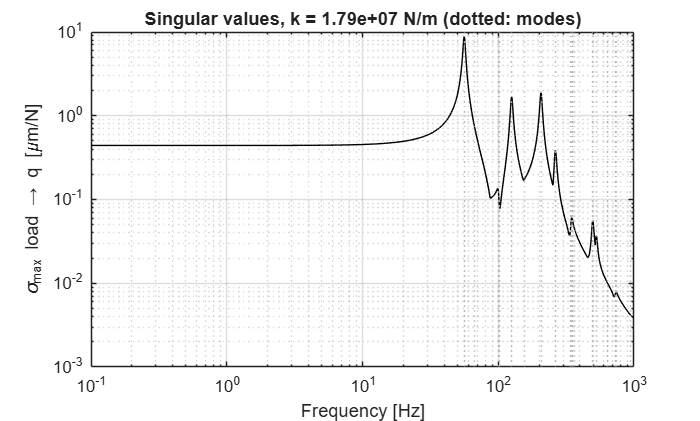


figure('Name','sigma');
loglog(w/2/pi, sv(1,:)*1e6, 'k'); hold on;
xline(fn(fn <= f_band(2)), ':', 'Color', [0.7 0.7 0.7]);
xlabel('Frequency [Hz]'); ylabel('\sigma_{max}  load \rightarrow q  [\mum/N]');
title(sprintf('Singular values, k = %.2e N/m (dotted: modes)', k_nom)); grid on;

### Bode magnitude per unit gust

A Bode magnitude plot shows how strongly a system responds to a sinusoidal input at each frequency so that we can find the **worst-case frequency**.

 Here the input is the gust $u'$, so the curve is $|y(j\omega)/u'(j\omega)|$: the output amplitude per 1 m/s of gust, plotted against frequency on log axes. One curve is drawn per elevation.

The four panels show four different outputs:

- **Sideways feed motion,** $q_y$: the feed moving relative to the dish along $y$. **This is the mechanical pointing error #1.**

- **Axial feed motion,** $q_z$: the feed moving along the boresight. This is the defocus term, **which costs gain** but does not move the beam.

- **Feed tilt,** $\mathrm{tilt}_x$: the feed rotating relative to the dish about the elevation axis.** Mechanical pointing error #2.**

- **Line of sight,** $\mathrm{LOS}_x$: the resulting beam pointing error about $x$. It combines dish tilt $\theta_{2x}$ with $(\mathrm{BDF}/f)\,q_y$, so it can show peaks from both the feed modes and the dish modes.

**How to read the plots? >> **The flat region at low frequency is quasi-static. The peaks are resonances, amplified by roughly $1/(2\zeta)=25$. [UNK] A curve is missing where that output is zero by symmetry, such as $q_y$ at 0 deg elevation, where the wind is purely axial. UNK

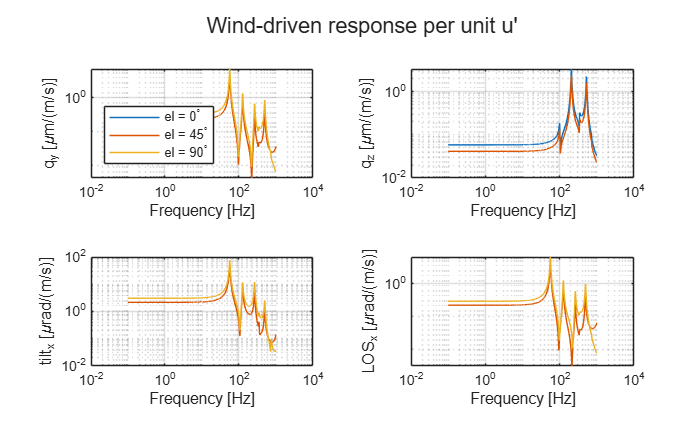

% Loop: for each elevation, scale the load plant by the wind influence vector
%       and store |output / u'| over the frequency grid
bodeOut = {2, 3, 4, 6};
bodeLbl = {'q_y [\mum/(m/s)]','q_z [\mum/(m/s)]','tilt_x [\murad/(m/s)]','LOS_x [\murad/(m/s)]'};
cols    = lines(numel(elev_deg));
mag     = zeros(numel(outNames), numel(w), numel(elev_deg));
for ie = 1:numel(elev_deg)
    bw   = windInfluence(P, deg2rad(elev_deg(ie)));
    sysW = sysLoad*bw;                               % mechss, input = u'
    mag(:,:,ie) = squeeze(bode(sysW, w));            % 9 x nw
end

% Loop: one tile per output, one curve per elevation (symmetry zeros clipped)
figure('Name','bode');
tl = tiledlayout(2,2);
tl.Title.String = 'Wind-driven response per unit u''';
for p = 1:4
    nexttile(p); ref = max(mag(bodeOut{p},:,:), [], 'all');
    for ie = 1:numel(elev_deg)
        loglog(w/2/pi, 1e6*clip(mag(bodeOut{p},:,ie), ref), 'Color', cols(ie,:)); hold on;
    end
    grid on; xlabel('Frequency [Hz]'); ylabel(bodeLbl{p});
end
legend(nexttile(1), compose('el = %d^\\circ', elev_deg), 'Location', 'southwest');

% TODO: RETRIEVE WORST CASE FOR EACH ELEVATION - ANGLE / DISPLACEMENT.

### Check the gust spectrum

This plot shows $S_u$ against frequency in Hz. $S_u$ is the gust's power spectral density: the gust variance per unit bandwidth, in $(\mathrm{m/s})^2/\mathrm{Hz}$. It is one-sided, so the total area under the curve (on linear axes) equals the gust variance $\sigma_u^2$.

- **Flat part, at low frequency:** slow variations from the largest eddies, about the size of $L_u$.

- **Corner:** near $f_c=\bar{U}/(\sqrt{70.8}\,L_u)$, about 0.06 Hz for the default inputs.

- **Sloping part:** the $f^{-5/3}$ fall-off. This is the energy that reaches the structural modes at 15 to 1000 Hz.

**Von Kármán vs. real turbulence.** The black curve is the von Kármán model [6, 7], a fit to measured atmospheric turbulence rather than the turbulence itself. The red dashed curve is what the shaping filter actually feeds the model. The closer the red curve tracks the black one in the band where the structure has modes, the more trustworthy the RMS results.

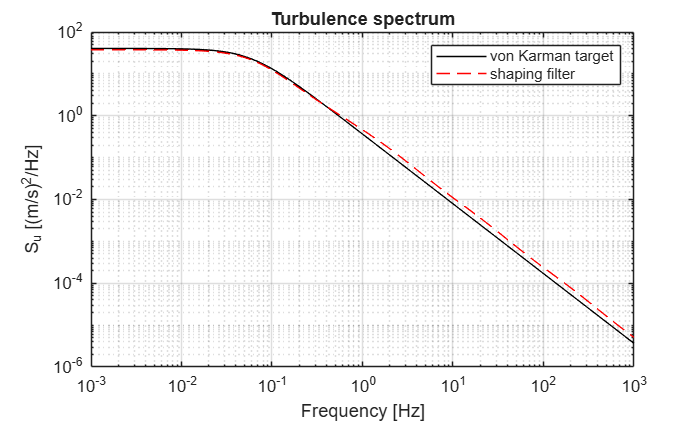

fW    = logspace(-3, log10(f_band(2)), 500);
sig_u = P.I_u*P.U_mean;
S_vk  = 4*sig_u^2*Tl ./ (1 + 70.8*(fW*Tl).^2).^(5/6);    % one-sided, per Hz
S_H   = 2*squeeze(abs(freqresp(Hw, 2*pi*fW))).'.^2;      % filter output, per Hz

figure('Name','wind PSD');
loglog(fW, S_vk, 'k', fW, S_H, 'r--'); grid on;
xlabel('Frequency [Hz]'); ylabel('S_u [(m/s)^2/Hz]');
legend('von Karman target','shaping filter'); title('Turbulence spectrum');

## Sweep: static offsets, statistical RMS and peak MAX

For each strut stiffness and each elevation, the script does three things.

**1. Static offsets.** A static offset is the steady, time-averaged displacement the structure settles into under constant loads, with no vibration. Two constant loads act here: the mean wind, $\frac{1}{2}\rho C A\bar{U}^2$ on each surface, and gravity. Because they do not change in time, mass and damping play no part, and the offset is the solution of


$$K\mathbf{x}_{static}=\mathbf{F}_{static}$$


At elevation $\varepsilon$, gravity points along $-(\cos\varepsilon\,\hat{y}+\sin\varepsilon\,\hat{z})$ in the dish frame. The gravity load is $M$ times $g$ on every translational DOF, which also gives the correct moment from the dish's centre-of-mass offset.

**Why static offsets are kept separate.** The covariance in step 2 describes only the fluctuation about the mean, so the mean has to be found separately.

- **Gravity sag** repeats exactly at each elevation. A pointing model or the focus and feed alignment can calibrate it out, so it is reported but not counted as jitter.

- **The mean-wind offset** changes with wind speed and direction over minutes, so a static pointing model cannot remove it. It is added to MAX.

**2. RMS from the Lyapunov equation.** Write the structure in first-order state-space form and drive it with the shaping filter's white noise $w$:


$$\dot{\mathbf{x}}=A\mathbf{x}+B\,w,\qquad E\left[w(t)\,w(\tau)\right]=W\,\delta(t-\tau)$$


If $A$ is stable, the state covariance $P=E\left[\mathbf{x}\mathbf{x}^{T}\right]$ settles to a constant. That constant is the unique solution of the continuous-time Lyapunov equation


$$AP+PA^{T}+BWB^{T}=0$$


and the output covariance is $CPC^{T}$. Its diagonal gives the variance $\sigma^2$ of each output. This is the exact value of the spectral integral $\sigma^2=\frac{1}{2\pi}\int|H(j\omega)|^2W\,d\omega$, found without any time simulation or frequency grid. The equation is named after A. M. Lyapunov, who introduced it for stability analysis [14]. Its use for the covariance of linear systems driven by white noise is standard in stochastic control [13]. MATLAB's `covar` solves it through `lyap` [15]. Here $W=1$, because the filter is already scaled to the gust RMS.

**3. Peak MAX.** For a Gaussian random signal, the average rate of upward zero crossings is Rice's formula [12], $\nu_0=\frac{1}{2\pi}\frac{\sigma_{\dot{y}}}{\sigma_y}$. Over an exposure time $T$, Davenport's peak factor [11]


$$g=\sqrt{2\ln(\nu_0 T)}+\frac{0.5772}{\sqrt{2\ln(\nu_0 T)}}$$


gives the expected largest peak, $\mathrm{MAX}=y_{mean}+g\,\sigma$, where $y_{mean}$ is the size of the mean-wind offset.

Metrics with x and y parts combine them, for example $\sigma_{lat}=\sqrt{\sigma_x^2+\sigma_y^2}$.

% For every (k, elevation):
%   build M, C, K for this k (once per k; loads change with elevation)
%   static offsets: solve K x = F for mean wind and for gravity
%   stochastic: plant (displacement + velocity outputs) in series with the
%     shaping filter; output covariance from the Lyapunov equation (covar)
%   per metric: sigma, zero-upcrossing rate nu, peak factor g(nu*T),
%     MAX = |mean-wind offset| + g * sigma
nk = numel(k_vals); ne = numel(elev_deg); ng = numel(grp);
RMS = nan(nk, ne, ng); MAX = RMS; MEANW = RMS; GRAV = RMS; NU = RMS;
f_lat = nan(nk,1);                                   % dominant feed-lateral mode

for ik = 1:nk
    mdl = buildModel(P, k_vals(ik));
    f_lat(ik) = mdl.f_feed_lat;

    % Dense first-order form, reused for every elevation (input = 5 loads)
    nd = size(mdl.M,1);
    A  = [zeros(nd) eye(nd); -mdl.M\mdl.K  -mdl.M\mdl.C];
    BL = [zeros(nd,5); mdl.M\mdl.B];
    Cy = blkdiag(mdl.Fy, mdl.Fy);                    % [displacement; velocity] outputs

    for ie = 1:ne
        el       = deg2rad(elev_deg(ie));
        [bw, fm] = windInfluence(P, el);

        % Static offsets (dish frame). Gravity load = M * (g on every translational DOF).
        g_vec  = -9.81*[0; cos(el); sin(el)];
        Fg     = mdl.M*repmat([g_vec; 0; 0; 0], nd/6, 1);
        y_wind = mdl.Fy*(mdl.K\(mdl.B*fm));
        y_grav = mdl.Fy*(mdl.K\Fg);

        % Turbulent response covariance via Lyapunov
        sysT = ss(A, BL*bw, Cy, 0)*Hw;               % white noise -> [y; ydot]
        Pc   = covar(sysT, 1);
        varY = diag(Pc(1:9,1:9));  varV = diag(Pc(10:18,10:18));

        % Loop: reduce each output group to RMS, Davenport peak factor, MAX
        for ig = 1:ng
            idx  = grp{ig};
            sig  = sqrt(sum(varY(idx)));
            nu   = sqrt(sum(varV(idx)))/(2*pi*sig);
            xpk  = sqrt(2*log(max(nu*P.T_expo, exp(1))));   % guarded for small nu*T
            RMS(ik,ie,ig)   = sig;
            NU(ik,ie,ig)    = nu;
            MEANW(ik,ie,ig) = norm(y_wind(idx));
            GRAV(ik,ie,ig)  = norm(y_grav(idx));
            MAX(ik,ie,ig)   = MEANW(ik,ie,ig) + (xpk + 0.5772/xpk)*sig;
        end
    end
    fprintf('%2d/%2d  k = %.2e N/m  f_feed,lat = %6.1f Hz  RMS LOS(el=%d) = %.3g urad\n', ...
            ik, nk, k_vals(ik), f_lat(ik), elev_deg(end), 1e6*RMS(ik,end,4));
end

 1/31  k = 1.00e+06 N/m  f_feed,lat =   19.0 Hz  RMS LOS(el=90) = 5.6 urad
 2/31  k = 1.26e+06 N/m  f_feed,lat =   21.1 Hz  RMS LOS(el=90) = 4.52 urad
 3/31  k = 1.58e+06 N/m  f_feed,lat =   23.4 Hz  RMS LOS(el=90) = 3.67 urad
 4/31  k = 2.00e+06 N/m  f_feed,lat =   25.8 Hz  RMS LOS(el=90) = 3 urad
 5/31  k = 2.51e+06 N/m  f_feed,lat =   28.4 Hz  RMS LOS(el=90) = 2.47 urad
 6/31  k = 3.16e+06 N/m  f_feed,lat =   31.2 Hz  RMS LOS(el=90) = 2.05 urad
 7/31  k = 3.98e+06 N/m  f_feed,lat =   34.1 Hz  RMS LOS(el=90) = 1.72 urad
 8/31  k = 5.01e+06 N/m  f_feed,lat =   37.2 Hz  RMS LOS(el=90) = 1.46 urad
 9/31  k = 6.31e+06 N/m  f_feed,lat =   40.4 Hz  RMS LOS(el=90) = 1.25 urad
10/31  k = 7.94e+06 N/m  f_feed,lat =   43.7 Hz  RMS LOS(el=90) = 1.09 urad
11/31  k = 1.00e+07 N/m  f_feed,lat =   47.2 Hz  RMS LOS(el=90) = 0.953 urad
12/31  k = 1.26e+07 N/m  f_feed,lat =   50.7 Hz  RMS LOS(el=90) = 0.847 urad
13/31  k = 1.58e+07 N/m  f_feed,lat =   54.3 Hz  RMS LOS(el=90) = 0.762 urad
14/31  k = 2.

## Results vs strut stiffness

Solid lines are RMS and dashed lines are MAX, with one colour per elevation. The dotted vertical line marks the aluminium tube's stiffness. On the LOS panel, the red dash-dot line is the HPBW/10 pointing budget. The last panel shows the dominant natural frequency of the feed moving sideways.

**Reading the curves.** Where a curve flattens out, the struts are no longer the weak link. The joints or the base now limit the response, and stiffer struts stop helping.

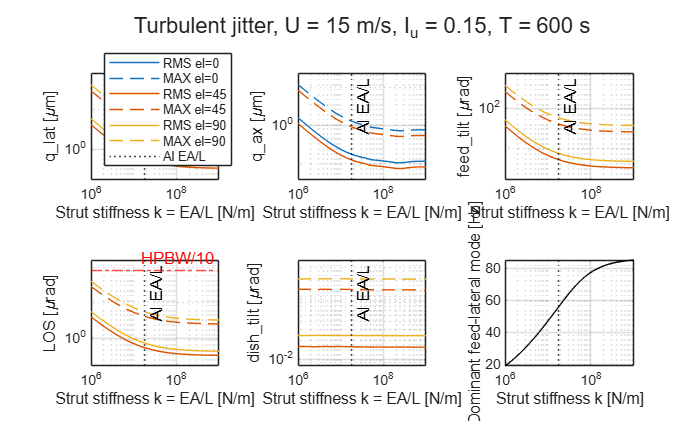

% Loop: one tile per metric, RMS and MAX curves per elevation
figure('Name','jitter vs k');
tl = tiledlayout(2,3);
tl.Title.String = sprintf('Turbulent jitter, U = %g m/s, I_u = %.2f, T = %g s', ...
                          P.U_mean, P.I_u, P.T_expo);
for ig = 1:ng
    nexttile; ref = max(MAX(:,:,ig), [], 'all');
    for ie = 1:ne
        loglog(k_vals, grpScale(ig)*clip(RMS(:,ie,ig), ref), '-',  'Color', cols(ie,:)); hold on;
        loglog(k_vals, grpScale(ig)*clip(MAX(:,ie,ig), ref), '--', 'Color', cols(ie,:));
    end
    xline(k_nom, 'k:', 'Al EA/L');
    if ig == 4, yline(1e6*HPBW/10, 'r-.', 'HPBW/10'); end
    xlabel('Strut stiffness k = EA/L [N/m]'); ylabel([texName(grpNames{ig}) ' [' grpUnits{ig} ']']);
    grid on; axis tight; ylim(ylim.*[0.5 2]);        % pad log axis so flat curves show
end
nexttile;                                            % feed-lateral mode vs. k
semilogx(k_vals, f_lat, 'k'); xline(k_nom, 'k:');
xlabel('Strut stiffness k [N/m]'); ylabel('Dominant feed-lateral mode [Hz]'); grid on;
% Legend entries follow plotting order: RMS, MAX per elevation, then the xline
legend(nexttile(1), [reshape([compose('RMS el=%d', elev_deg); ...
       compose('MAX el=%d', elev_deg)], 1, []), {'Al EA/L'}], 'Location','southwest');

### Static offsets

Solid lines are the mean-wind offset and dashed lines are gravity sag, both from $K\mathbf{x}_{static}=\mathbf{F}_{static}$. They are steady offsets, not jitter. Use them to check feed alignment and focus budgets, and to confirm the displacements stay small enough for the linear model.

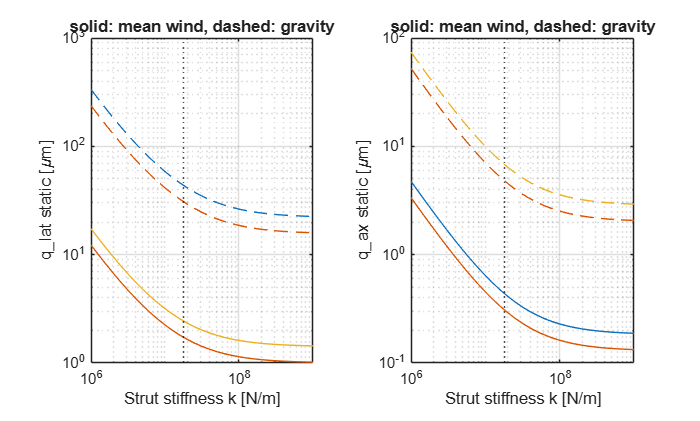

% Loop: lateral and axial panels, wind and gravity curves per elevation
figure('Name','static offsets'); tiledlayout(1,2);
for p = 1:2
    nexttile; ref = max([MEANW(:,:,p) GRAV(:,:,p)], [], 'all');
    for ie = 1:ne
        loglog(k_vals, 1e6*clip(MEANW(:,ie,p), ref), '-',  'Color', cols(ie,:)); hold on;
        loglog(k_vals, 1e6*clip(GRAV(:,ie,p), ref),  '--', 'Color', cols(ie,:));
    end
    xline(k_nom,'k:'); grid on; xlabel('Strut stiffness k [N/m]');
    ylabel([texName(grpNames{p}) ' static [\mum]']);
    title('solid: mean wind, dashed: gravity');
end

## Save the data

Results go to a `results` folder next to this script:

- a long-format CSV with one row per stiffness, elevation and metric (units: m and rad);

- a .mat file with every result array and the parameter structure `P`.

[KK, EE, GG] = ndgrid(k_vals, elev_deg, 1:ng);
results = table(KK(:), EE(:), categorical(grpNames(GG(:)).'), ...
                RMS(:), MAX(:), MEANW(:), GRAV(:), NU(:), ...
    'VariableNames', {'k_N_per_m','elev_deg','metric','rms','max','mean_wind', ...
                      'gravity_static','nu0_Hz'});
scriptDir = fileparts(which('feed_jitter_mechss'));
if isempty(scriptDir), scriptDir = pwd; end
outDir = fullfile(scriptDir, 'results');
if ~exist(outDir, 'dir'), mkdir(outDir); end
writetable(results, fullfile(outDir, 'feed_jitter_mechss_results.csv'));
save(fullfile(outDir, 'feed_jitter_mechss_results.mat'), 'P', 'k_vals', 'elev_deg', ...
     'grpNames', 'RMS', 'MAX', 'MEANW', 'GRAV', 'NU', 'f_lat', 'results');
fprintf('Saved results to %s (units: m and rad)\n', outDir);

Saved results to C:\Users\17818\Desktop\Main\Personal\reflector-structural-dynamics\results (units: m and rad)


fprintf('HPBW at %.0f GHz = %.0f urad; LOS RMS at Al k, el=45: %.3g urad\n', ...
        P.rf_Hz/1e9, 1e6*HPBW, 1e6*interp1(log(k_vals), RMS(:,2,4), log(k_nom)));

HPBW at 225 GHz = 799 urad; LOS RMS at Al k, el=45: 0.539 urad


## References

Citations were compiled from the literature and should be checked against the originals before formal use.

- [1] Y. T. Lo, "On the beam deviation factor of a parabolic reflector," IRE Transactions on Antennas and Propagation, vol. 8, no. 3, pp. 347–349, 1960.

- [2] J. Ruze, "Lateral-feed displacement in a paraboloid," IEEE Transactions on Antennas and Propagation, vol. 13, no. 5, pp. 660–665, 1965.

- [3] J. W. M. Baars, The Paraboloidal Reflector Antenna in Radio Astronomy and Communication. Springer, 2007.

- [4] R. Levy, Structural Engineering of Microwave Antennas. IEEE Press, 1996.

- [5] W. Gawronski, Modeling and Control of Antennas. Springer, 2008.

- [6] T. von Kármán, "Progress in the statistical theory of turbulence," Proceedings of the National Academy of Sciences, vol. 34, no. 11, pp. 530–539, 1948.

- [7] J. D. Holmes, Wind Loading of Structures, 3rd ed. CRC Press, 2015.

- [8] ESDU 85020, Characteristics of atmospheric turbulence near the ground, Part II: single point data for strong winds (neutral atmosphere). ESDU International.

- [9] U.S. Department of Defense, MIL-HDBK-1797, Flying Qualities of Piloted Aircraft, 1997 (von Kármán turbulence transfer functions; see also MIL-F-8785C, 1980, and the MATLAB Aerospace Blockset "Von Karman Wind Turbulence Model (Continuous)" documentation).

- [10] A. N. Kolmogorov, "The local structure of turbulence in incompressible viscous fluid for very large Reynolds numbers," Doklady Akademii Nauk SSSR, vol. 30, 1941.

- [11] A. G. Davenport, "Note on the distribution of the largest value of a random function with application to gust loading," Proceedings of the Institution of Civil Engineers, vol. 28, no. 2, pp. 187–196, 1964.

- [12] S. O. Rice, "Mathematical analysis of random noise," Bell System Technical Journal, vol. 23, pp. 282–332, 1944, and vol. 24, pp. 46–156, 1945.

- [13] H. Kwakernaak and R. Sivan, Linear Optimal Control Systems. Wiley-Interscience, 1972.

- [14] A. M. Lyapunov, The General Problem of the Stability of Motion, 1892; English translation in International Journal of Control, vol. 55, no. 3, 1992.

- [15] The MathWorks, Control System Toolbox documentation: mechss, covar, lyap, sigma, bode.

- [16] J. S. Przemieniecki, Theory of Matrix Structural Analysis. McGraw-Hill, 1968.

- [17] EN 1991-1-4, Eurocode 1: Actions on structures, Part 1-4: Wind actions, Annex B, 2005.

## Local functions

These are described in **Functions used in this script** at the top.

function mdl = buildModel(P, k_truss)
% Assemble M, K, modal C, load matrix B and output matrix Fy for one strut stiffness.
%   allocate 6 DOF for m1, m2 and every strut node
%   put the rigid-body mass blocks of m1 (at its CG) and m2 (at the vertex,
%   with its CG offset c2 coupling translation and rotation) on the diagonal
%   build one beam element in local axes (same for every element)
%   for each strut:
%       place it from the rim (angle phi) to the ring on m1
%       rotate the element to the strut direction and stamp N_el copies
%       stamp a joint bushing rim->first node and last node->m1 ring
%   stamp the base spring from the m2 pivot to ground
%   modal decomposition, then C = M V diag(2 zeta w) V' M  (mass-normalized V)
%   build load (B) and output (Fy) selection matrices
    nNode = P.N_el + 1;
    ndof  = 12 + P.n_truss*nNode*6;
    K = zeros(ndof); M = zeros(ndof);
    M(1:6,1:6)   = blkdiag(P.m1*eye(3), P.J1);                 % m1 about its CG
    cx = skew([0; 0; P.c2]);                                    % m2 CG offset from vertex
    M(7:12,7:12) = [P.m2*eye(3), -P.m2*cx; P.m2*cx, P.J2];      % m2 about the vertex
    i1 = 1:6; i2 = 7:12;                                        % m1, m2 DOF indices

    % Strut section: k_truss sets E for the fixed tube; m_truss sets density
    L   = hypot(P.r_dish - P.r_ring, P.z_feed - P.z_rim);
    Le  = L/P.N_el;
    A   = pi*(P.d_o^2 - (P.d_o-2*P.t_wall)^2)/4;
    I   = pi*(P.d_o^4 - (P.d_o-2*P.t_wall)^4)/64;
    J   = 2*I;
    E   = k_truss*L/A;  G = E/(2*(1+P.nu));
    rho = P.m_truss/(A*L);
    me  = rho*A*Le;                                  % element mass

    % 12x12 Euler-Bernoulli 3D frame element, consistent mass, local axes.
    %   local DOF order per node: [u v w thx thy thz]
    %   axial and torsion: 2-node bar; bending in x-y and x-z planes: Hermite cubic
    %   (x-z plane uses the sign-flipped coupling because dw/dx = -thy)
    Kl = zeros(12); Ml = zeros(12);
    bar = [1 -1; -1 1]; cbar = [2 1; 1 2]/6;
    Kl([1 7],[1 7])   = E*A/Le*bar;   Ml([1 7],[1 7])   = me*cbar;
    Kl([4 10],[4 10]) = G*J/Le*bar;   Ml([4 10],[4 10]) = rho*J*Le*cbar;
    kb = E*I/Le^3*[12 6*Le -12 6*Le; 6*Le 4*Le^2 -6*Le 2*Le^2; ...
                   -12 -6*Le 12 -6*Le; 6*Le 2*Le^2 -6*Le 4*Le^2];
    mb = me/420*[156 22*Le 54 -13*Le; 22*Le 4*Le^2 13*Le -3*Le^2; ...
                 54 13*Le 156 -22*Le; -13*Le -3*Le^2 -22*Le 4*Le^2];
    S  = diag([1 -1 1 -1]);
    iy = [2 6 8 12]; iz = [3 5 9 11];
    Kl(iy,iy) = kb;      Ml(iy,iy) = mb;
    Kl(iz,iz) = S*kb*S;  Ml(iz,iz) = S*mb*S;

    r1 = [0; 0; P.z_feed];                           % m1 reference point (its CG)

    % Loop: assemble each strut and its two joints
    for i = 1:P.n_truss
        phi   = 2*pi*(i-1)/P.n_truss;
        p_bot = [P.r_dish*cos(phi); P.r_dish*sin(phi); P.z_rim];
        p_top = [P.r_ring*cos(phi); P.r_ring*sin(phi); P.z_feed];
        u     = (p_top - p_bot)/L;                   % strut axis, rim -> feed
        lam   = localAxes(u);
        nodeIdx = @(j) 12 + ((i-1)*nNode + (j-1))*6 + (1:6);

        % Element matrices rotated to the dish frame
        T  = kron(eye(4), lam);
        Ke = T.'*Kl*T;  Me = T.'*Ml*T;

        % Loop: stamp beam elements along the strut
        for e = 1:P.N_el
            idx = [nodeIdx(e) nodeIdx(e+1)];
            K(idx,idx) = K(idx,idx) + Ke;
            M(idx,idx) = M(idx,idx) + Me;
        end

        % Joint bushing: axial/lateral stiffness about the strut axis, isotropic rotation
        Kj = blkdiag(lam.'*diag([P.k_joint_ax P.k_joint_lat P.k_joint_lat])*lam, ...
                     P.k_joint_rot*eye(3));
        K  = addLink(K, i2, rigidMap(p_bot), nodeIdx(1), eye(6), Kj);          % rim joint
        K  = addLink(K, nodeIdx(nNode), eye(6), i1, rigidMap(p_top - r1), Kj); % feed joint
    end

    % Base: translational k_base + rotational k_base_rot at the pivot, to ground
    Kbase = blkdiag(P.k_base*eye(3), P.k_base_rot*eye(3));
    K = addLink(K, i2, rigidMap([0; 0; -P.e_base]), [], [], Kbase);
    K = (K + K.')/2;  M = (M + M.')/2;

    % Modes and explicit 2% modal damping
    [V, D] = eig(K, M);
    [w2, ord] = sort(diag(D)); V = V(:,ord);
    V  = V ./ sqrt(diag(V.'*M*V)).';                 % mass-normalize
    wn = sqrt(max(w2, 0));
    C  = M*V*diag(2*P.zeta*wn)*V.'*M;  C = (C + C.')/2;

    % Load inputs: [F_feed_y F_feed_z F_dish_y F_dish_z M_dish_x]
    B = zeros(ndof, 5);
    B(2,1) = 1; B(3,2) = 1; B(8,3) = 1; B(9,4) = 1; B(10,5) = 1;

    % Outputs: q = x1 - x2 + skew(r1) theta2  (= x1 - (x2 + theta2 x r1))
    Q  = zeros(3,ndof); Q(:,1:3) = eye(3); Q(:,7:9) = -eye(3); Q(:,10:12) = skew(r1);
    Tt = zeros(2,ndof); Tt(:,4:5) = eye(2); Tt(:,10:11) = -eye(2);   % feed tilt
    Th = zeros(2,ndof); Th(:,10:11) = eye(2);                        % dish tilt
    % LOS: dish rotation + beam deviation from lateral feed offset (opposite sense)
    LOSx = Th(1,:) + P.BDF/P.f_dish*Q(2,:) + P.c_tilt*Tt(1,:);
    LOSy = Th(2,:) - P.BDF/P.f_dish*Q(1,:) + P.c_tilt*Tt(2,:);
    Fy   = [Q; Tt; LOSx; LOSy; Th];

    % Dominant feed-lateral mode: largest modal contribution to the static
    % q_y response under a lateral feed force, (Q_y phi)(phi' b) / w^2
    contrib = abs((Q(2,:)*V) .* (B(:,1).'*V)) ./ max(w2.', eps);
    [~, iLat] = max(contrib);

    mdl = struct('M',M,'K',K,'C',C,'B',B,'Fy',Fy,'fn',wn/(2*pi), ...
                 'f_feed_lat',wn(iLat)/(2*pi));
end

function K = addLink(K, ia, Ta, ib, Tb, Kb)
% Stamp a 6x6 spring between point a (DOFs ia, map Ta) and point b (ib, Tb).
%   relative motion d = Ta*q_a - Tb*q_b, energy 1/2 d' Kb d -> K += G' Kb G
%   empty ib means point b is ground
    if isempty(ib)
        Gm = Ta; idx = ia;
    else
        Gm = [Ta, -Tb]; idx = [ia ib];
    end
    K(idx,idx) = K(idx,idx) + Gm.'*Kb*Gm;
end

function T = rigidMap(r)
% Motion of a point at offset r on a rigid body: x_p = x + theta x r = x - skew(r) theta.
    T = [eye(3), -skew(r); zeros(3), eye(3)];
end

function S = skew(r)
% Cross-product matrix: skew(r)*v = r x v.
    S = [0 -r(3) r(2); r(3) 0 -r(1); -r(2) r(1) 0];
end

function lam = localAxes(u)
% Rotation matrix whose rows are the local axes: x along u, y and z perpendicular.
    ref = [0; 0; 1];
    if abs(dot(u, ref)) > 0.9, ref = [1; 0; 0]; end
    ey  = cross(ref, u); ey = ey/norm(ey);
    ez  = cross(u, ey);
    lam = [u.'; ey.'; ez.'];
end

function [bw, fmean] = windInfluence(P, el)
% Wind loads in the dish frame for elevation el (wind horizontal, in the elevation plane,
% blowing onto the concave face). Direction in dish frame: [0, sin(el), -cos(el)].
%   coefficient*area for each of the 5 load inputs
%   dish moment = centre-of-pressure lever arm + aero moment C_M*sin(2 el)
%   bw    = rho U * coef      (fluctuating load per unit u')
%   fmean = 1/2 rho U^2 coef  (mean-wind static load)
    s = sin(el); c = cos(el);
    coef = [ P.Cd_feed*P.A_feed*s;  -P.Cd_feed*P.A_feed*c; ...
             P.C_S*P.A_dish*s;      -P.C_N*P.A_dish*c;  0];
    coef(5) = -P.z_cp*coef(3) + 2*P.r_dish*P.A_dish*P.C_M*sin(2*el);
    bw    = P.rho_air*P.U_mean*coef;
    fmean = 0.5*P.rho_air*P.U_mean^2*coef;
end